clear all
clc
s = tf('s');

Plant transfer function.

G = 100/(s*(s+1)*(s+10))

G =
 
          100
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.



I chose canonical form from all the available opitions to get the state-space form of the system.

csys = canon(G,'companion')

csys =
 
  A = 
        x1   x2   x3
   x1    0    0    0
   x2    1    0  -10
   x3    0    1  -11
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0    0  100
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A = csys.A;
B = csys.B;
C = csys.C;

Compute the desirerd poles using the second-order approximation of the system. The plan is to place the third pole far away as compared to the two poles obtained from the calculation so that the third pole does not have much impact on the system.

MO = 20;
ts = 6;

Compute the damping ratio

z = -log(MO/100)/sqrt(pi^2 + (log(MO/100))^2)

z = 0.4559

Compute natuaral frequency

w = 4/(ts*z)

w = 1.4621

Finding desired poles of the system from the characteristic equation.

p = roots([1 2*z*w w^2]);
poles = [p(1) p(2) -10];

Place the poles at the desired location.

K = place(A,B,poles)

K =     0.3333    1.8045   -1.8045


Set the observer poles far away from the controller poles so that the observer does not interfere with the system response.

l = [-80,-81,-82];

Place observer poles.

L  = place(A',C',l)

L = 	1.0e+03 *

    5.3136    0.1967    0.0023


L = L';

Create a regulator for the plant using the obtained K and L values.

feedback = reg(csys,K,L);
AA = feedback.A;
BB = feedback.B;
CC = feedback.C;
DD = feedback.D;

Convert state-space to transfer funciton for the reguator.

[Ns,Ds] = ss2tf(AA,BB,CC,DD);
S = [s^3,s^2,s,1];
tf = (S*Ns')/(S*Ds')

tf =
 
     -2122 s^2 - 3.258e04 s - 1.136e05
  ---------------------------------------
  s^3 + 243.3 s^2 + 1.976e04 s + 5.384e05
 
Continuous-time transfer function.



Compute the closed loop tranfer funciton.

TF = 100/((s*(s+1)*(s+10))-100*tf)

TF =
 
                     100 s^3 + 2.433e04 s^2 + 1.976e06 s + 5.384e07
  ------------------------------------------------------------------------------------
  s^6 + 254.3 s^5 + 2.245e04 s^4 + 7.582e05 s^3 + 6.332e06 s^2 + 8.642e06 s + 1.136e07
 
Continuous-time transfer function.



Convert the closed loop system to state-space canonical form.

sys = canon(TF,'companion')

sys =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           0           0  -1.136e+07
   x2           1           0           0           0           0  -8.642e+06
   x3           0           1           0           0           0  -6.332e+06
   x4           0           0           1           0           0  -7.582e+05
   x5           0           0           0           1           0  -2.245e+04
   x6           0           0           0           0           1      -254.3
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
 
  C = 
               x1          x2          x3          x4          x5          x6
   y1           0           0         100       -1100    1.11e+04  -1.111e+05
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



The poles of the combined system to identify the plant states:

pole(sys)

System resposnse for using the initial conditions.

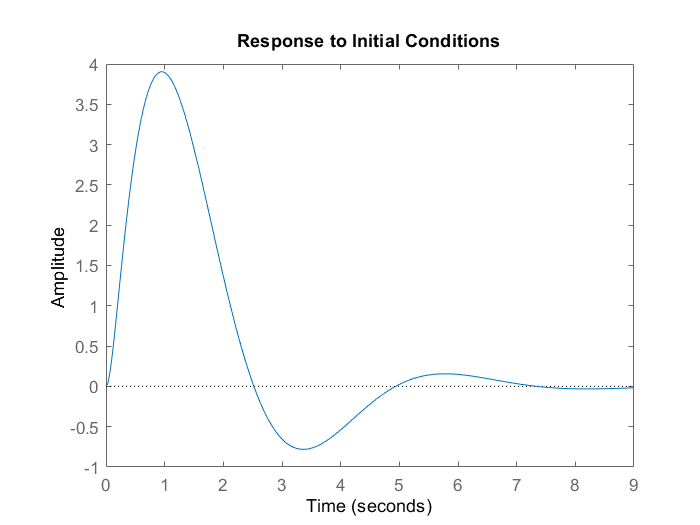

ans =   -0.6667 + 1.3013i
  -0.6667 - 1.3013i
 -10.0000 + 0.0000i
 -80.0000 + 0.0000i
 -81.0000 + 0.0000i
 -82.0000 + 0.0000i


initial(sys,[1 0 0 0 0 0])

System performance

stepinfo(sys)

ans = struct with fields:
        RiseTime: 1.0822
    SettlingTime: 5.7951
     SettlingMin: 4.3202
     SettlingMax: 5.6748
       Overshoot: 19.7439
      Undershoot: 0
            Peak: 5.6748
        PeakTime: 2.4868
